**Explore Factor Stucture underlying the Personality Scores in the HCP **

**1.1) Factor Analysis - 2 Factors (Horn Parallel Analysis) **

personality_scores = [HCP_behavioral_532.NEOFAC_A, HCP_behavioral_532.NEOFAC_O, HCP_behavioral_532.NEOFAC_C, HCP_behavioral_532.NEOFAC_N, HCP_behavioral_532.NEOFAC_E]

personality_scores =     29    23    26    21    32
    37    24    35    15    37
    31    33    36     7    15
    36    22    36     2    26
    35    30    45     8    31
    29    34    38    18    27
    26    39    27    12    27
    34    30    42     5    35
    38    27    41     8    29
    36    31    21    17    32


personality_scores_normalized = normalize(personality_scores)

personality_scores_normalized =    -0.8459   -0.9287   -1.4552    0.5991    0.2831
    0.5659   -0.7670    0.1233   -0.2041    1.0824
   -0.4929    0.6886    0.2987   -1.2749   -2.4346
    0.3894   -1.0904    0.2987   -1.9442   -0.6761
    0.2130    0.2034    1.8771   -1.1410    0.1232
   -0.8459    0.8503    0.6494    0.1975   -0.5162
   -1.3753    1.6589   -1.2798   -0.6056   -0.5162
    0.0365    0.2034    1.3510   -1.5426    0.7626
    0.7424   -0.2818    1.1756   -1.1410   -0.1965
    0.3894    0.3651   -2.3321    0.0637    0.2831


[sMEV, ciEV, cumE, resL2, nBasis] = HornParallelAnalysis(personality_scores_normalized,1000)

sMEV =     1.1478
    1.0638
    0.9978
    0.9331
    0.8638


ciEV =     1.0555    1.2401
    0.9867    1.1408
    0.9274    1.0682
    0.8625    1.0038
    0.7851    0.9425


cumE =     0.3799
    0.6101
    0.7571
    0.8862
    1.0000


resL2 =    40.5770
   32.1727
   25.3973
   17.3801
    0.0000


nBasis = 2

[Loadings, specVar, T, stats, F_2_Factors] = factoran(personality_scores,nBasis) % change here the number of Factors

Loadings =     0.4965    0.0662
    0.0922    0.4298
    0.4317   -0.5031
   -0.6007    0.2698
    0.6340    0.0666


specVar =     0.7491
    0.8067
    0.5605
    0.5663
    0.5936


T =     0.9361   -0.3519
    0.3519    0.9361


stats = struct with fields:
    loglike: -4.3273e-06
        dfe: 1
      chisq: 0.0023
          p: 0.9619


F_2_Factors =    -0.8785    0.7369
    0.8853    0.0073
   -1.0639   -1.6626
    0.3459   -1.9946
    0.9927   -1.9230
   -0.4959   -0.5120
   -0.3875    1.6622
    1.4689   -1.2182
    0.7835   -1.5881
    0.1291    2.9788


**1.1) Factor Analysis - 1 Factor --> looking at p-value from chi-square **

[Loadings, specVar, T, stats, F_1_Factor] = factoran(personality_scores,1) % change here the number of Factors

Loadings =     0.4293
   -0.0544
    0.5189
   -0.7074
    0.5299


specVar =     0.8157
    0.9970
    0.7307
    0.4995
    0.7192


T = 1

stats = struct with fields:
    loglike: -0.0783
        dfe: 5
      chisq: 41.3404
          p: 8.0085e-08


F_1_Factor =    -1.0392
    0.7608
   -0.0369
    1.3728
    1.5784
   -0.3470
   -0.6261
    1.8666
    1.3630
   -0.6798


**2) Extract and plot factors **

factor_1_two_factors = F_2_Factors(:,1)

factor_1_two_factors =    -0.8785
    0.8853
   -1.0639
    0.3459
    0.9927
   -0.4959
   -0.3875
    1.4689
    0.7835
    0.1291


factor_2_two_factors = F_2_Factors(:,2)

factor_2_two_factors =     0.7369
    0.0073
   -1.6626
   -1.9946
   -1.9230
   -0.5120
    1.6622
   -1.2182
   -1.5881
    2.9788


factor_1_one_factor = F_1_Factor(:,1)

factor_1_one_factor =    -1.0392
    0.7608
   -0.0369
    1.3728
    1.5784
   -0.3470
   -0.6261
    1.8666
    1.3630
   -0.6798


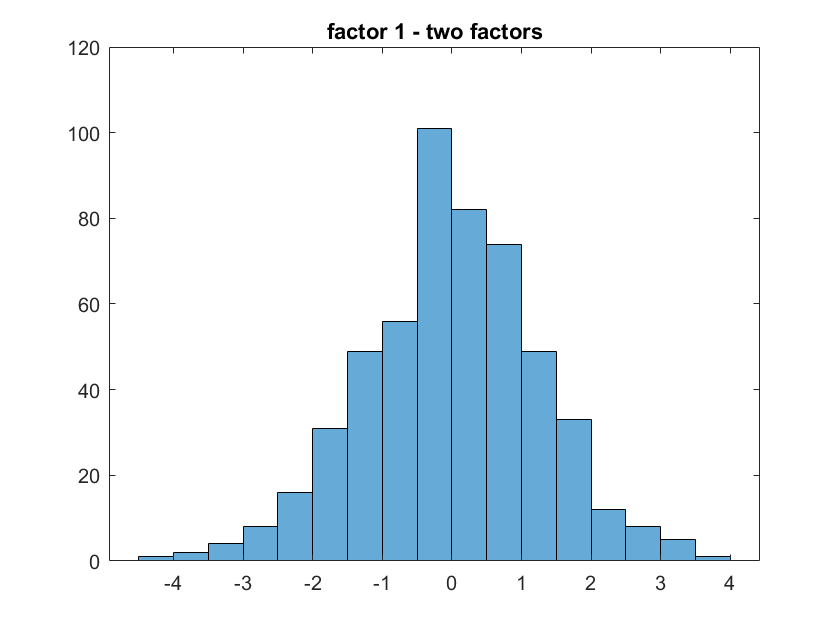


histogram(factor_1_two_factors)
title('factor 1 - two factors')

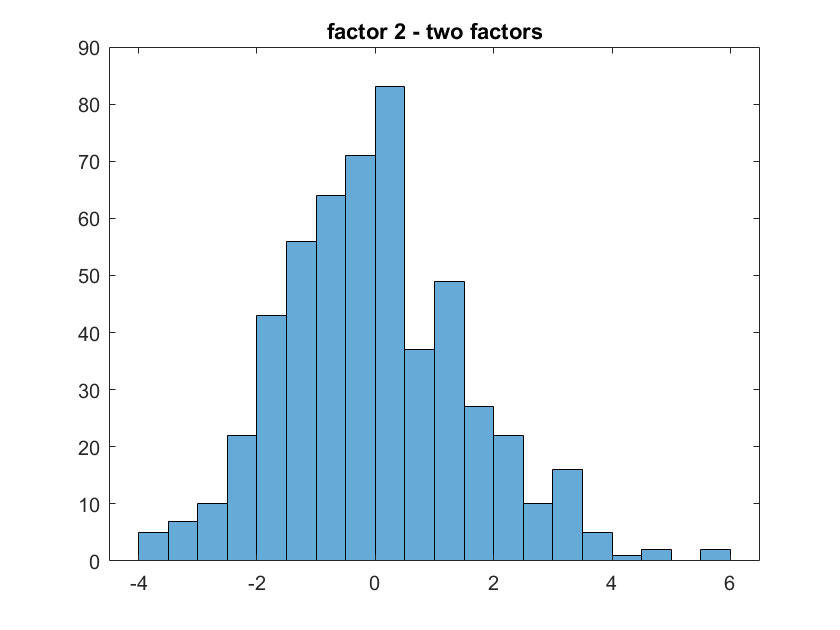


histogram(factor_2_two_factors)
title('factor 2 - two factors')

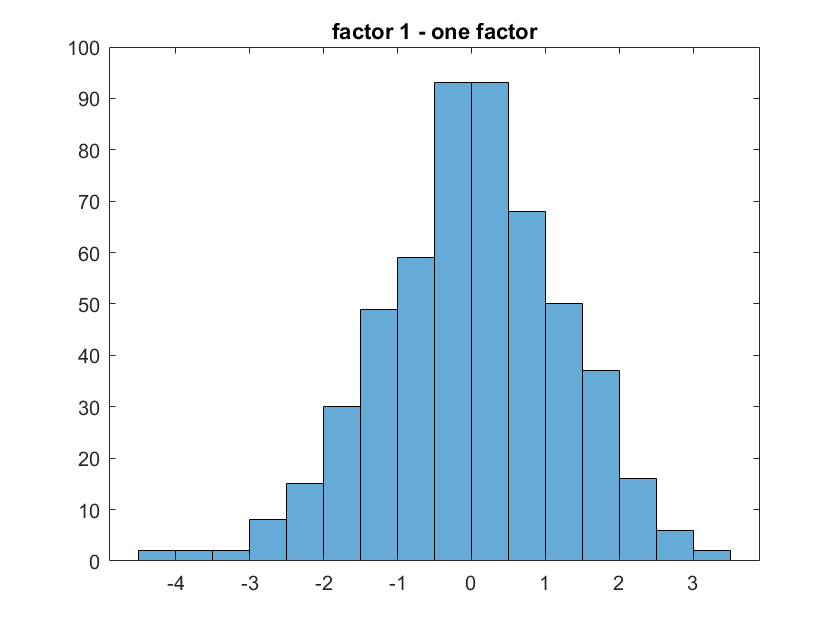


histogram(factor_1_one_factor)
title('factor 1 - one factor')

[r, pval] = corrcoef(factor_1_two_factors,factor_2_two_factors)

r =     1.0000    0.1875
    0.1875    1.0000


pval =     1.0000    0.0000
    0.0000    1.0000


**3) Safe factors **

Personality_Variables_from_factor_analysis_and_PCA = table(HCP_behavioral_532.("Subject Name"),factor_1_two_factors,factor_2_two_factors,factor_1_one_factor)

Factors_from_factor_analysis = 532×3 table
       Var1         Var2        Var3   
    __________    ________    _________

    {'100206'}    -0.87848      0.73688
    {'100307'}     0.88533    0.0073054
    {'100610'}     -1.0639      -1.6626
    {'101309'}     0.34591      -1.9946
    {'101915'}     0.99274       -1.923
    {'102311'}    -0.49594     -0.51204
    {'102513'}    -0.38751       1.6622
    {'102614'}      1.4689      -1.2182
    {'103111'}      0.7835      -1.5881
    {'103212'}     0.12911       2.9788
    {'103414'}     -0.3376      0.77652
    {'103818'}     -1.9646      -1.1364
    {'104416'}     0.75354      -1.6296
    {'105014'}     0.93065      -1.2893
    {'105115'}     -1.0827       1.4447
    {'105216'}     -2.1912       1.1173


Personality_Variables_from_factor_analysis_and_PCA.Properties.VariableNames = {'Subject Name', 'factor 1 - two factors', 'factor 2 - two factors', 'factor 1 - one factor'}

Factors_from_factor_analysis = 532×3 table
    Subject Name    factor 1    factor 2 
    ____________    ________    _________

     {'100206'}     -0.87848      0.73688
     {'100307'}      0.88533    0.0073054
     {'100610'}      -1.0639      -1.6626
     {'101309'}      0.34591      -1.9946
     {'101915'}      0.99274       -1.923
     {'102311'}     -0.49594     -0.51204
     {'102513'}     -0.38751       1.6622
     {'102614'}       1.4689      -1.2182
     {'103111'}       0.7835      -1.5881
     {'103212'}      0.12911       2.9788
     {'103414'}      -0.3376      0.77652
     {'103818'}      -1.9646      -1.1364
     {'104416'}      0.75354      -1.6296
     {'105014'}      0.93065      -1.2893
     {'105115'}      -1.0827       1.4447
     {'105216'}      -2.1912       1.1173


**2) PCA **

personality_scores = [HCP_behavioral_532.NEOFAC_A, HCP_behavioral_532.NEOFAC_O, HCP_behavioral_532.NEOFAC_C, HCP_behavioral_532.NEOFAC_N, HCP_behavioral_532.NEOFAC_E]

personality_scores =     29    23    26    21    32
    37    24    35    15    37
    31    33    36     7    15
    36    22    36     2    26
    35    30    45     8    31
    29    34    38    18    27
    26    39    27    12    27
    34    30    42     5    35
    38    27    41     8    29
    36    31    21    17    32


[coeff,score,latent, tsquared, explained, mu] = pca(personality_scores) 

coeff =    -0.3282    0.2627    0.4506    0.7875    0.0015
    0.0473    0.8486   -0.4127   -0.0279    0.3263
   -0.3816   -0.2865    0.0624   -0.1008    0.8708
    0.7298    0.1253    0.5915   -0.0767    0.3098
   -0.4603    0.3361    0.5224   -0.6025   -0.1983


score =     6.9190   -2.5991    3.2645   -4.1882   -8.0704
   -5.7739   -1.2990    6.0811   -1.3756   -2.7454
    0.5271   -3.9213  -16.4987    7.4154    2.9373
  -10.3461   -8.8721   -6.9176    5.4157   -4.3748
  -10.9964   -2.4918   -3.9470    0.0255    6.9385
    2.9721    1.2411   -4.9125   -2.4622    6.0304
    4.0121    7.0961  -12.5631   -3.3952   -3.7795
  -13.5538   -0.9264   -4.2698   -2.6395    2.6022
   -9.6761   -3.7758   -2.6515    4.0799    2.8775
    3.9885    6.9603    0.4393    1.9123  -11.0424


latent =    80.8298
   42.8857
   28.0580
   23.7766
   22.2479


tsquared =     4.7949
    2.1881
   12.7640
    6.9590
    4.3599
    2.8948
    8.1254
    3.5399
    2.8136
    6.9678


explained =    40.8648
   21.6816
   14.1852
   12.0206
   11.2478


mu =    33.7932   28.7425   34.2970   16.5244   30.2293


scores_component_1 = score(:,1)

scores_component_1 =     6.9190
   -5.7739
    0.5271
  -10.3461
  -10.9964
    2.9721
    4.0121
  -13.5538
   -9.6761
    3.9885


scores_component_2 = score(:,2)

scores_component_2 =    -2.5991
   -1.2990
   -3.9213
   -8.8721
   -2.4918
    1.2411
    7.0961
   -0.9264
   -3.7758
    6.9603


scores_component_3 = score(:,3)

scores_component_3 =     3.2645
    6.0811
  -16.4987
   -6.9176
   -3.9470
   -4.9125
  -12.5631
   -4.2698
   -2.6515
    0.4393


scores_component_4 = score(:,4)

scores_component_4 =    -4.1882
   -1.3756
    7.4154
    5.4157
    0.0255
   -2.4622
   -3.3952
   -2.6395
    4.0799
    1.9123


scores_component_5 = score(:,5)

scores_component_5 =    -8.0704
   -2.7454
    2.9373
   -4.3748
    6.9385
    6.0304
   -3.7795
    2.6022
    2.8775
  -11.0424


Personality_Variables_from_factor_analysis_and_PCA = table(HCP_behavioral_532.("Subject Name"),factor_1_two_factors,factor_2_two_factors,factor_1_one_factor, scores_component_1,scores_component_2, scores_component_3, scores_component_4, scores_component_5)

Personality_Variables_from_factor_analysis_and_PCA = 532×9 table
       Var1         Var2        Var3         Var4        Var5        Var6        Var7        Var8       Var9  
    __________    ________    _________    _________    _______    ________    ________    ________    _______

    {'100206'}    -0.87848      0.73688      -1.0392      6.919     -2.5991      3.2645     -4.1882    -8.0704
    {'100307'}     0.88533    0.0073054      0.76076    -5.7739      -1.299      6.0811     -1.3756    -2.7454
    {'100610'}     -1.0639      -1.6626    -0.036872    0.52712     -3.9213     -16.499      7.4154     2.9373
    {'101309'}     0.34591      -1.9946       1.3728    -10.346     -8.87

Personality_Variables_from_factor_analysis_and_PCA.Properties.VariableNames = {'Subject Name', 'factor 1 - two factors', 'factor 2 - two factors', 'factor 1 - one factor', 'scores_component_1' ,'scores_component_2' , 'scores_component_3' , 'scores_component_4', 'scores_component_5'}

Personality_Variables_from_factor_analysis_and_PCA = 532×9 table
    Subject Name    factor 1 - two factors    factor 2 - two factors    factor 1 - one factor    scores_component_1    scores_component_2    scores_component_3    scores_component_4    scores_component_5
    ____________    ______________________    ______________________    _____________________    __________________    __________________    __________________    __________________    __________________

     {'100206'}            -0.87848                   0.73688                   -1.0392                 6.919                -2.5991                3.2645               -4.1882              -8.0704      
     {'100307'} 